**Ecole Centrale de Lyon**

**STItc3 - Conversion Analogique Numérique **

**BE2 : Conversion Sigma Delta**

**Groupe élèves**

NOM Prénom: MARCON Adèle

NOM Prénom: FRELECHOUX Chloé

**Groupe de TP: C1A2**

**Date: 07/01/2026**

## 1) CANSurechantillonnage : observation de l'impact du sur-échantillonnage

Pequant = 5.0888e-06

PequantR = 5.0683e-06

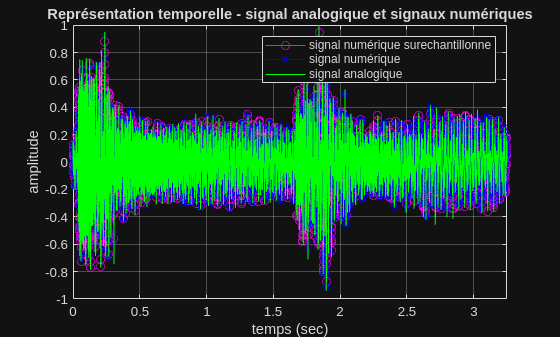

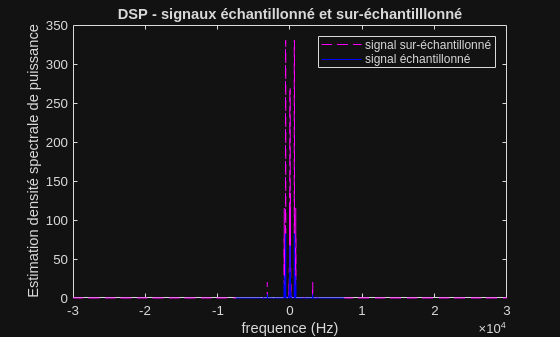

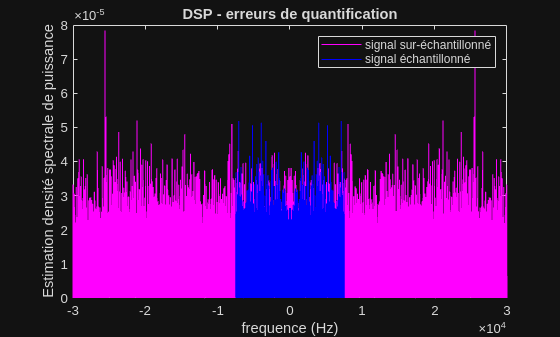

clear all;
close all;
clc;

%  Signal "analogique" x 
load glock.mat;     % contient data et nus
nuscont = nus;      % nuscont = 60000 Hz
x = data;
x = x/max(abs(x));  % normalisation de x dans [-1;+1]

nus = 15000;      % frequence d'echantillonnage (Hz)
R = 4;     % facteur de suréchantillonnage
nusR = R*nus;    % frequence de sur-echantillonnage (Hz)
Nbit = 8;  % nombre de bits de quantification
CANSurechantillonnage; % simulation et représentation des données


ecoute = 1; % booléen pour activer l'écoute des sons
if(ecoute)
sound(x,nuscont);
pause(4)
sound(xtild,nus);
pause(4);
sound(xtildR,nusR);
pause(4);
end

**Q1**

À l'oreille, on n'entend pas de différence entre les signaux

**Q2**

Les densités spectrales des signaux correspond à celles du cours. L'amplitude du signal sur-échantilloné est plus importante que celle du signal original et la DSP de l'erreur de quantification du signal sur-échantilloné est plus "étalée" en fréquence que celle du signal échantilloné.

**Q3**

Pour diminuer l'erreur de quantification, il faudrait ajouter un filtre passe-bas de fréquence de coupure nus/2 (ou utiliser un convertisseur Sigma-Delta).

## 2) Modulateur Sigma-Delta

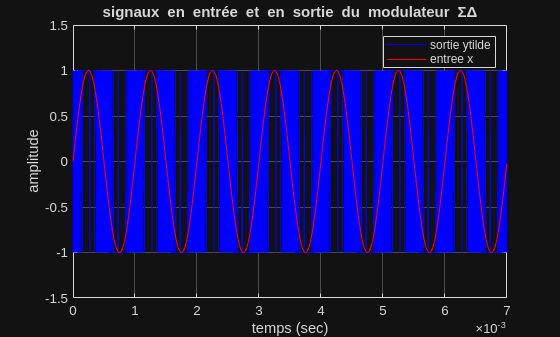

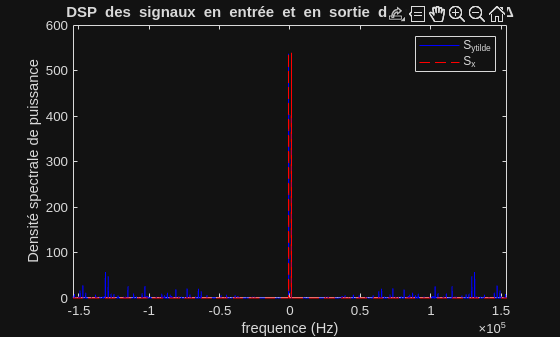

%  Paramètres de simulation 
nu0 = 1000;     % frequence du signal sinusoidale (Hz)
nus = 44000;   % frequence d'echantillonnage (Hz)

R = 7;        % facteur de sur-echantillonnage
mModulateurSigmaDelta; % simulation et représentation des données

**Q4**

Dans l'ordre: Bloc générateur de signal, [intégrateur, sur-échantillonage, quantification 1 Bits (et Bloc d'ordre 0)] (+ scope et sortie/entrée)

**Q5**

On a un sinus en entrée: donc 2 diracs (nu0 et -nu0) pour Sx et Sytilde

De plus pour Sytilde, on est en sorti du modulateur. D'après le cours, on devrait observer la densité spectrale de l'erreur de quantification dans les hautes fréquences. Après l'intégrateur, l'erreur de quantification apparaît, on applique ensuite un passe-haut sur cette erreur, ce qui explique l'absence de DSP d'erreur de quantification dans les basses fréquences et leur présence dans les hautes fréquences. Cette descprition correspond à celle observée.

## 3) Convertisseur Sigma-Delta

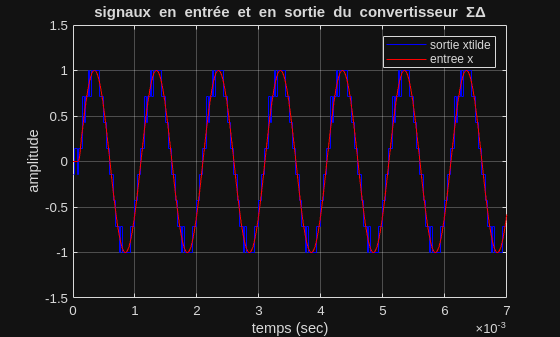

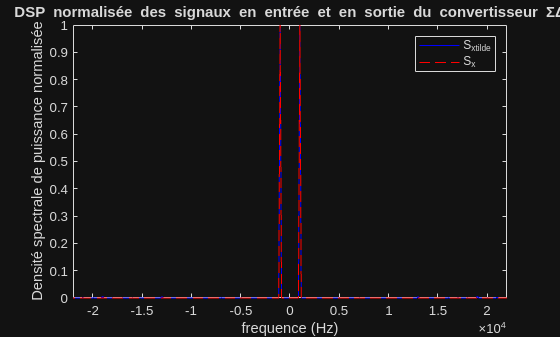

% Paramètres de simulation 
nu0 = 1000;     % frequence du signal sinusoidale (Hz)
nus = 44000;   % frequence d'echantillonnage (Hz)

% Filtre en sortie du modulateur SigmaDelta 
Nbit = 3;
L = 7;              % ordre du filtre
gk = ones(1,L)/L;   % coefficents de la réponse impulsionnelle du filtre
R = L;
mConvertisseurSigmaDelta; % simulation et représentation des données

**Q6**

Dans l'ordre: Bloc générateur de signal, filtre anti-repliement, modulateur = [intégrateur, sur-échantillonage, quantification 1 Bits (et Bloc d'ordre 0)], Filtre passe-bas, décimation. (+ scope et sortie/entrée)

**Q7**

Ce filtre est un filtre passe-bas qui permet d'élminer l'erreur de quantification en haute fréquence. On peut observer L+1 valeurs en sortie de filtre, cela correspond à la somme de L échantillons pouvant prendre 2 valeurs (0 ou 1). D'après le cours, le filtre doit permettre au signal en sortie de prendre 2^Nbits valeurs donc: L = 2^Nbits - 1

**Q8**

La réponse impulsionnelle du filtre est composée de L diracs. On peut considérer que c'est le produit d'un peigne de dirac et d'un rectangle. Avec la TF, on obtient un sinus cardianl pour le rectangle. Lorsque nu = 1/L*Ts, le sinc s'annule (car = fréquence de coupure). Donc L = R

**Q9**

En certais points, on ne prend pas la valeur la plus proche: on fait parfois une erreur locale plus importate mais elle est globalement moins importante car on a un système non-linéaire. Ici, l'élément non-linéaire est la quantification 1 bit.